clear; 
close all;

%number_of_variables:  the dimension of the parameters that we need to solve
%fitness_function: the fitness function for selecting the gene 
%    population_size: the population 
%    parent_number: the number of individuals lefting in every generation(每一代中保持不变的个体数目)
%    mutation_rate:变异概率
%    maximal_generation:最大演化代数（循环次数）
%   minimal_cost:最小目标值（函数值越小，适应度越高）
[best_fitness, elite, generation, last_generation] = my_ga(3, 'my_fitness', 10, 4, 0.1, 100, 1.0e-6);

% disp(best_fitness(9990:10000,:));
% disp(elite(9990:10000,:))
disp(last_generation); 

     0



i_begin = last_generation - 8;

disp(best_fitness((generation+i_begin):(last_generation+generation)));

    1.0417
    1.0417
    1.0417
    0.7987
    0.5008
    0.2942
    0.2942
    0.2942
    0.2741



% the best solution 
my_elite = elite((generation+i_begin):(last_generation+generation),:);
disp(my_elite);

    0.8802    0.8497    0.9501
    0.8802    0.8497    0.9501
    0.8802    0.8497    0.9501
    0.8802    0.8497    0.9501
    0.8802    0.8497    0.9501
    0.8802    0.8497    0.9501
    0.8882    0.8497    0.9501
    0.8882    0.8497    0.9501
    0.8882    0.8497    0.9501



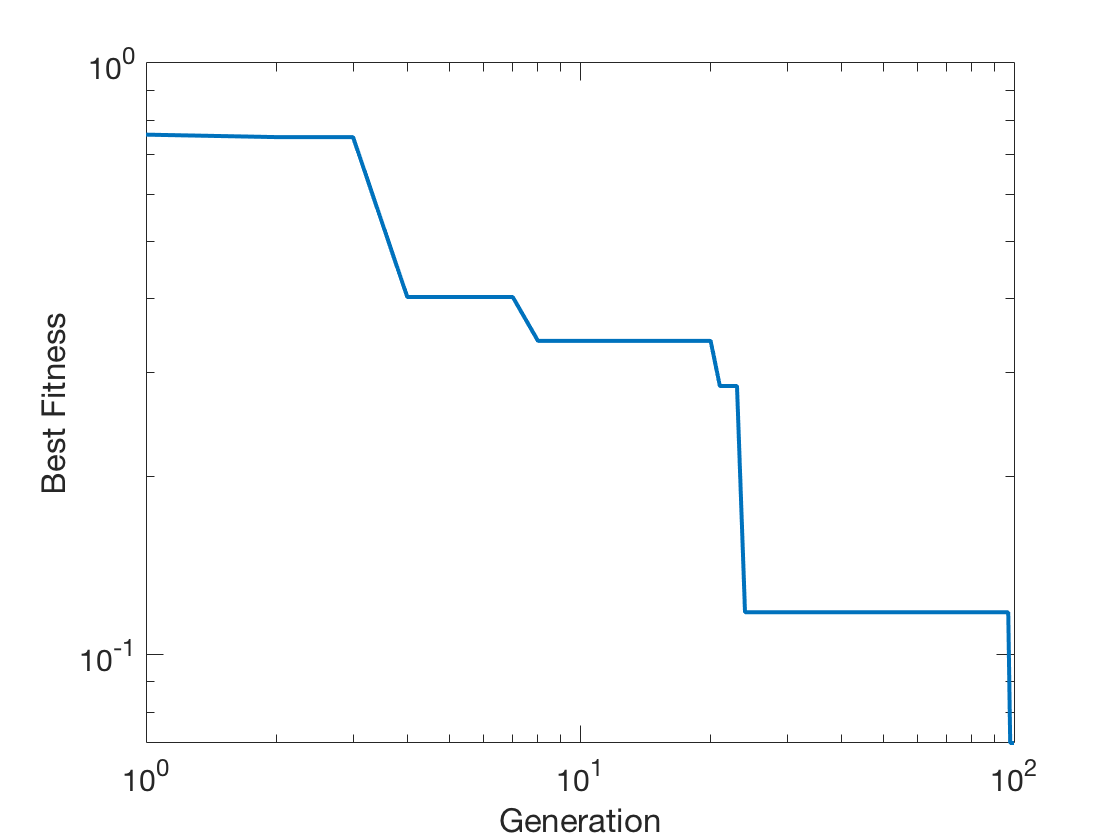

% fitness
figure
loglog(1:generation, best_fitness(1:generation,1), 'linewidth',2)
xlabel('Generation','fontsize',15);
ylabel('Best Fitness','fontsize',15);
set(gca,'fontsize',15,'ticklength',get(gca,'ticklength')*2);

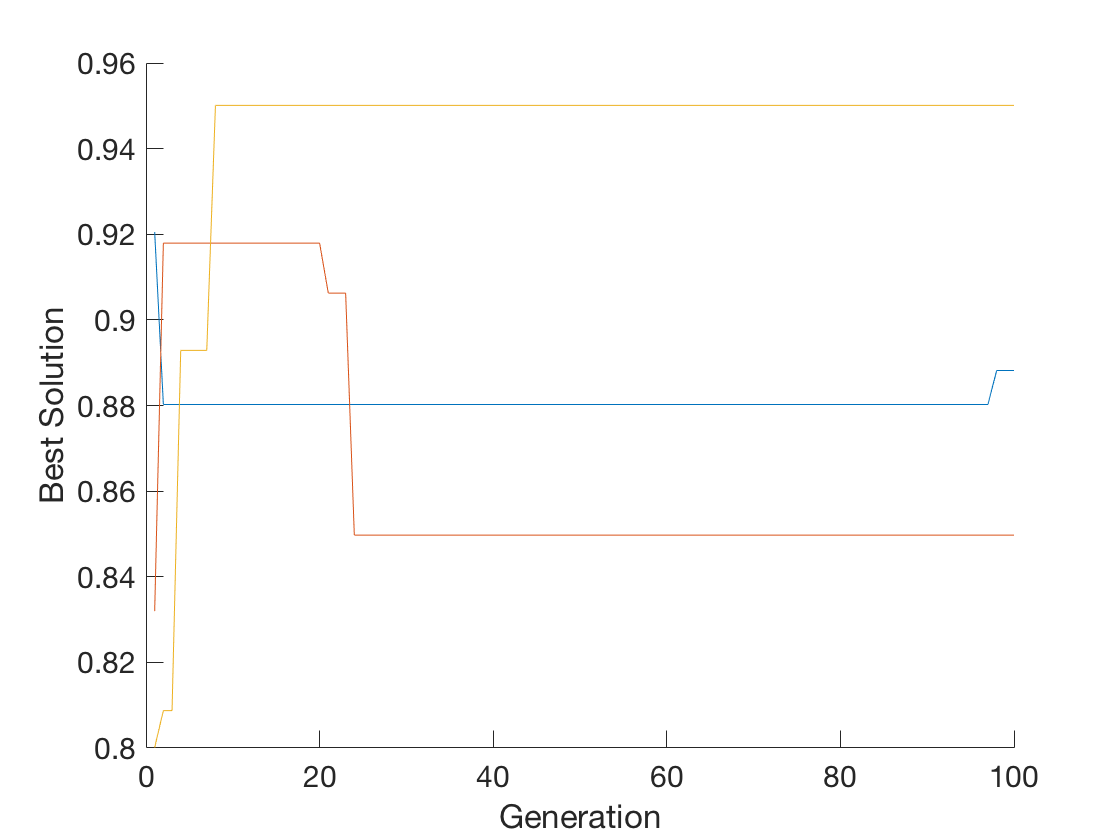

% the best solution 
figure
hold on 
semilogx(1 : generation, elite(1 : generation, 1))
semilogx(1 : generation, elite(1 : generation, 2))
semilogx(1 : generation, elite(1 : generation, 3))
xlabel('Generation','fontsize',15);
ylabel('Best Solution','fontsize',15);
set(gca,'fontsize',15,'ticklength',get(gca,'ticklength')*2);
hold off 